## Identifying a model for a PMSM

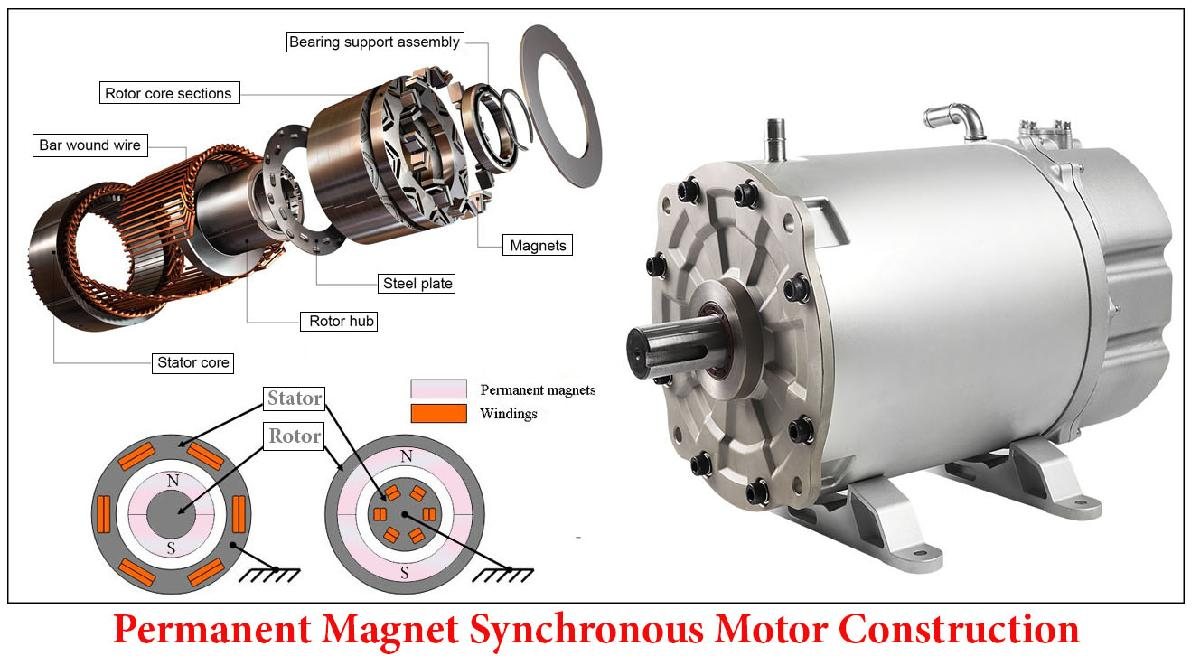

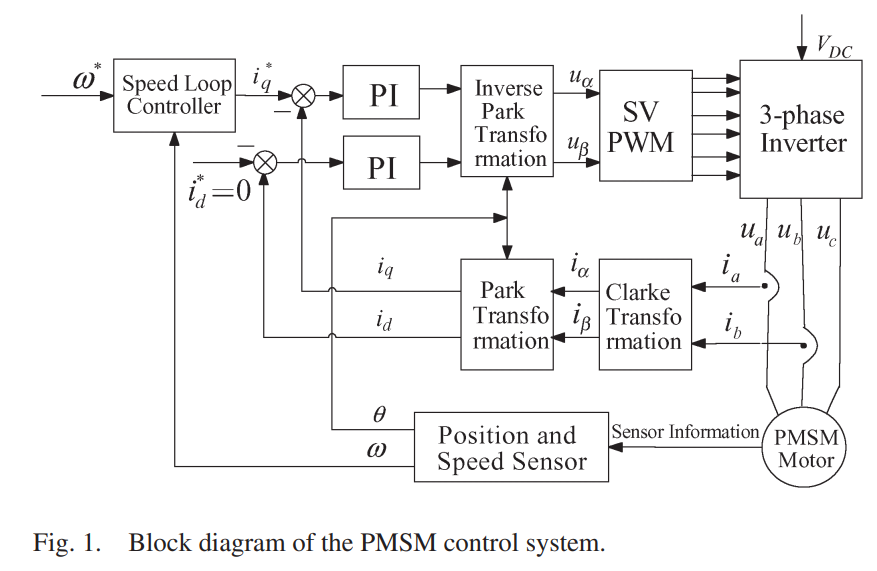

From Li and Liu IEEE tr Industrial Electronics 2012

The motor is governed by the following system of differential equations

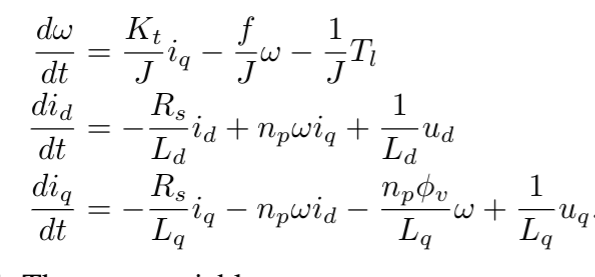

## Generate input data


h = 0.01;
uu = idinput(1200, 'rbs', [0, 0.5]);
u1 = 4*uu(1:600);
u1v = 4*uu(601:1200);
t = (0:599)'*h;
pmsm_input = cat(2, t, u1);
pmsm_input_val = cat(2, t, u1v);


## Load and plot data

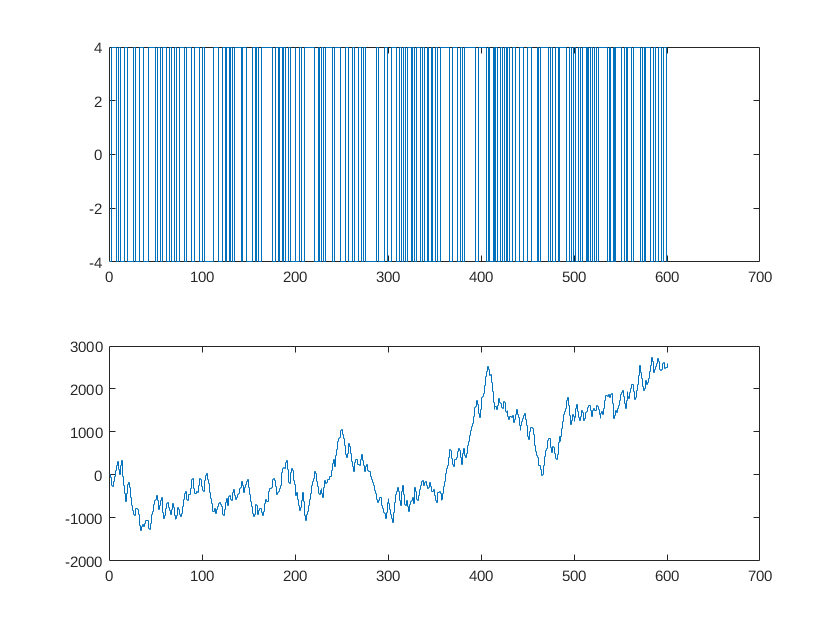

 load pmsm_sysid_sim.mat
 uident = uy.Data(:,1);
 yident = uy.Data(:,2);
 clear uy
 
 load pmsm_sysid_sim_val.mat
 uval = uy.Data(:,1);
 yval = uy.Data(:,2);
 clear uy


figure()
subplot(211);
stairs(uident)
subplot(212)
stairs(yident)

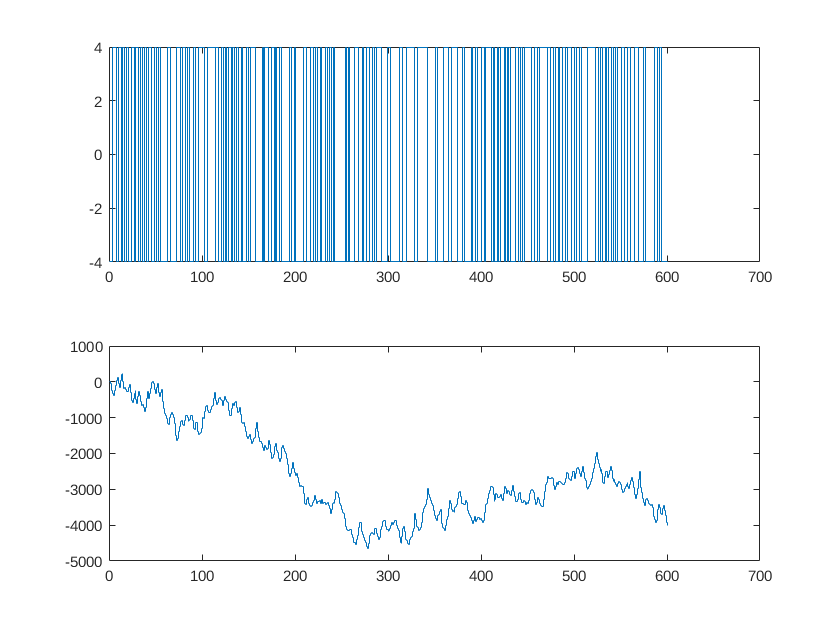


figure()
subplot(211);
stairs(uval)
subplot(212)
stairs(yval)

## Estimate models

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

% Second order model, one zero, two poles, one delay
% (b0 z + b1) / (z^2 + a1z + a2)
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.14 z^-1 + 0.148 z^-2                
                                                   
  B(z) = 4.895 z^-1 + 21.16 z^-2                   
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 93.37% (prediction focus)
FPE: 4852, MSE: 4756                             



% Second order model, one zero, two poles, two delays
% (b0 z + b1) /(z*(z^2 + a1z + a2))
arx222 = arx(iddta1, [2, 2, 2])

arx222 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.186 z^-1 + 0.1925 z^-2              
                                                   
  B(z) = 23.98 z^-2 - 3.453 z^-3                   
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 93.21% (prediction focus)
FPE: 5089, MSE: 4989                             



% Second order model, two zeros, two poles, one delay
% (b0 z^2 + b1z + b_2) /(z*(z^2 + a1z + a2))
arx231 = arx(iddta1, [2, 3, 1])

arx231 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.199 z^-1 + 0.2058 z^-2              
                                                   
  B(z) = 4.645 z^-1 + 21.43 z^-2 - 2.4 z^-3        
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=3   nk=1
   Number of free coefficients: 5
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 93.4% (prediction focus) 
FPE: 4843, MSE: 4716                             



% third order model, two zeros, three poles, one delay
% (b0 z^2 + b1z^1 + b2) / (z^3 + a1z^2 + a2z + a3)
arx331 = arx(iddta1, [3, 3, 1])

arx331 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.253 z^-1 + 0.4207 z^-2 - 0.1621 z^-3
                                                   
  B(z) = 4.625 z^-1 + 19.96 z^-2 - 0.9894 z^-3     
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 93.6% (prediction focus) 
FPE: 4565, MSE: 4430                             



% fourth order model, three zeros, four poles, one delay
% (b0 z^3 + b1z^2 + b2z + b3) / (z^4 + a1z^3 + a2z^2 + a3z + a4)
arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)               
  A(z) = 1 - 1.26 z^-1 + 0.4856 z^-2 - 0.2172 z^-3 - 0.002005 z^-4
                                                                  
  B(z) = 4.602 z^-1 + 20.17 z^-2 - 1.436 z^-3 + 2.371 z^-4        
                                                                  
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 93.63% (prediction focus)
FPE: 4574, MSE: 4395                             



% Fifth order model, four zeros, five poles, one delay
arx551 = arx(iddta1, [5, 5, 1])

arx551 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                             
  A(z) = 1 - 1.262 z^-1 + 0.5182 z^-2 - 0.2963 z^-3 + 0.1213 z^-4 - 0.07547 z^-5
                                                                                
  B(z) = 4.661 z^-1 + 20.24 z^-2 - 1.458 z^-3 + 2.435 z^-4 - 0.1046 z^-5        
                                                                                
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=5   nk=1
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 93.67% (prediction focus)
FPE: 4556, MSE: 4334                             



% sixth order model, five zeros, six poles, one delay
arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                
                                                                                   
  A(z) = 1 - 1.255 z^-1 + 0.5074 z^-2 - 0.2747 z^-3 + 0.06932 z^-4 - 0.003871 z^-5 
                                                                  - 0.03804 z^-6   
                                                                                   
                                                                                   
  B(z) = 4.605 z^-1 + 20.35 z^-2 - 1.327 z^-3 + 2.389 z^-4 + 0.01599 z^-5          
                                                                   - 0.4366 z^-6   
                                                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                       


% eigth order model, seven zeros, eight poles, one delay
arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                               
                                                                                  
  A(z) = 1 - 1.261 z^-1 + 0.5167 z^-2 - 0.2766 z^-3 + 0.06667 z^-4 - 0.02376 z^-5 
                                    - 0.03707 z^-6 + 0.07831 z^-7 - 0.05909 z^-8  
                                                                                  
                                                                                  
  B(z) = 4.622 z^-1 + 20.37 z^-2 - 1.416 z^-3 + 2.363 z^-4 + 0.03153 z^-5         
                                        + 0.08978 z^-6 - 2.342 z^-7 + 1.518 z^-8  
                                                                                  
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                


% 12th order model, 
arx12121 = arx(iddta1, [12, 12, 1])

arx12121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                   
                                                                                      
  A(z) = 1 - 1.266 z^-1 + 0.5178 z^-2 - 0.2594 z^-3 + 0.03936 z^-4 + 0.003444 z^-5    
          - 0.05098 z^-6 + 0.08265 z^-7 - 0.05947 z^-8 + 0.00712 z^-9 + 0.03204 z^-10 
                                                - 0.03797 z^-11 - 0.005209 z^-12      
                                                                                      
                                                                                      
  B(z) = 4.66 z^-1 + 20.12 z^-2 - 1.417 z^-3 + 2.548 z^-4 + 0.1662 z^-5               
          - 0.2008 z^-6 - 2.113 z^-7 + 1.774 z^-8 - 0.08248 z^-9 - 0.7879 z^-10       
                                                    + 2.359 z^-11 - 0.9748 z^-12      
                                                                                      
Sample time: 0.01 seconds
  
Par

## Compare models

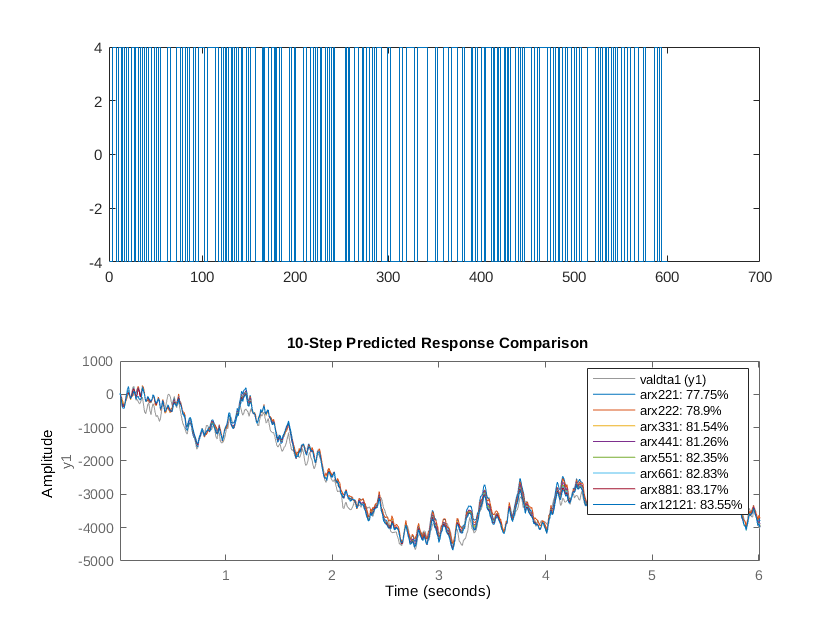

% Integrator model
im = tf([1, 0], [1, -1], h);
compare(valdta1, arx221, arx222, arx331, arx441, arx551, arx661, arx881, arx12121,10)

aic(arx221, arx222, arx331,arx441, arx661, arx881, arx12121)

Model quality according to the "nAIC" measure:
    8.4872    8.5349    8.4262    8.4281    8.4301    8.4350    8.4516



## Check poles and zeros

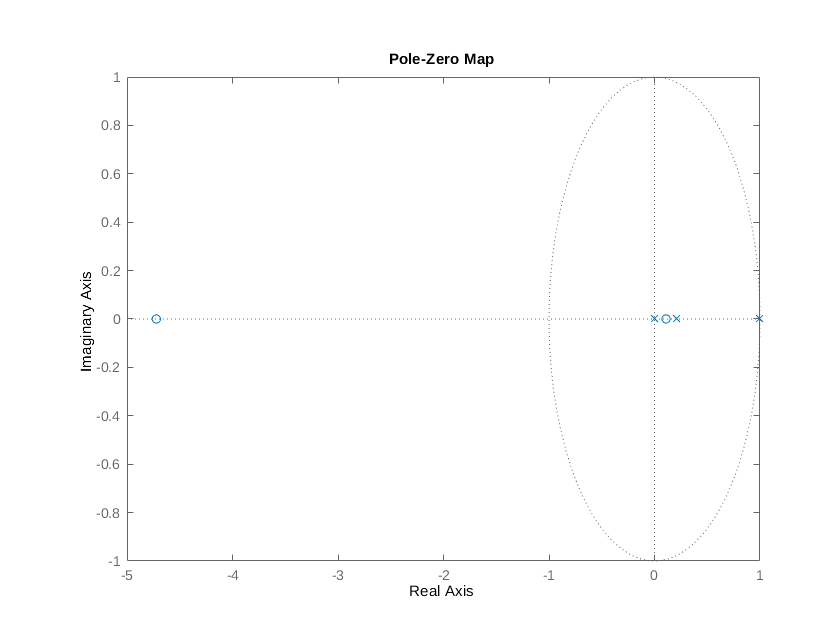

figure
pzmap(arx231)

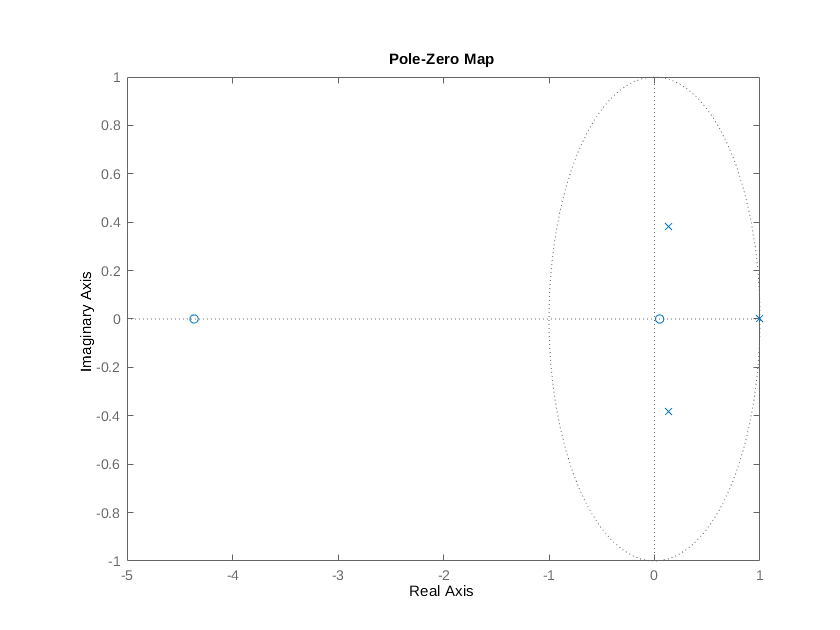

figure
pzmap(arx331)

## Residual analysis

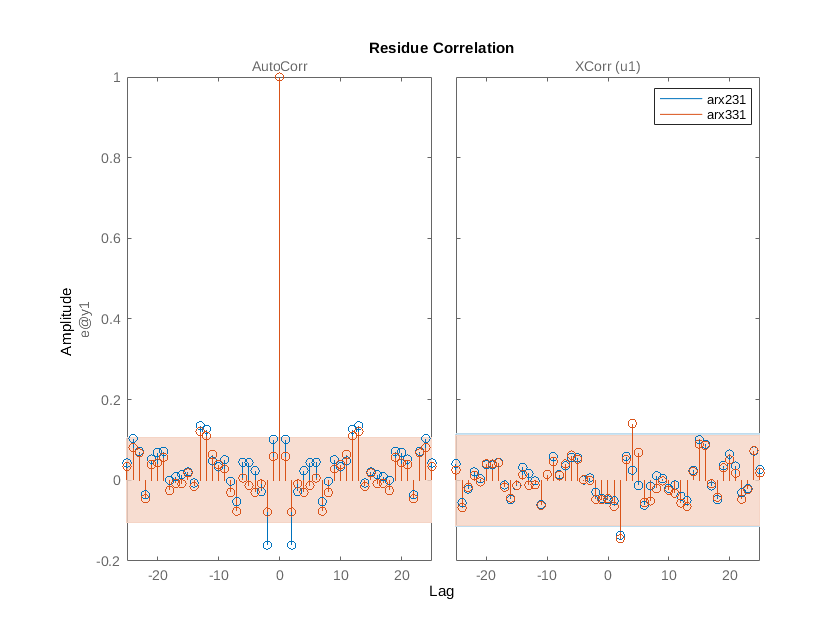

%resid(valdta1, arx221, arx331, arx661)
resid(valdta1, arx231, arx331)
legend

## The 3rd order model

[num, den] = tfdata(arx331);
G3 = tf(num{1}, den{1}, h)

G3 =
 
     4.625 z^2 + 19.96 z - 0.9894
  -----------------------------------
  z^3 - 1.253 z^2 + 0.4207 z - 0.1621
 
Sample time: 0.01 seconds
Discrete-time transfer function.



[num, den] = tfdata(arx231);
G33 = tf(num{1}, den{1}, h)

G33 =
 
  4.645 z^2 + 21.43 z - 2.4
  --------------------------
  z^3 - 1.199 z^2 + 0.2058 z
 
Sample time: 0.01 seconds
Discrete-time transfer function.

